# 62743 DSP – Uge 11 Tirsdag

% FIR design via Fourier transform (LP + BP)
clear; close all; clc;


## Common FFT settings

Nfft = 2048;

## Exercise 1 – FIR Low-pass (Fourier-transform design)

## 1-A) Cutoff and ideal LP impulse response

Fs = 8000;
Fc = 800;
wc = 2*pi*Fc/Fs;          % 0.2*pi rad/sample

fprintf('--- Exercise 1-A ---\n');

--- Exercise 1-A ---


fprintf('omega_c = %.6f rad/sample (%.3f*pi)\n', wc, wc/pi);

omega_c = 0.628319 rad/sample (0.200*pi)



% Ideal (infinite-length) LP impulse response
hLP_ideal = @(n) (n==0).*(wc/pi) + ...
                 (n~=0).*(sin(wc*n)./(pi*n));


## 1-B) 7-tap LP FIR coefficients

Ntaps1 = 7;
M1 = Ntaps1 - 1;          % 6
K1 = (Ntaps1 - 1)/2;      % 3

n_trunc = -K1:K1;         % -3:3
hLP_trunc = hLP_ideal(n_trunc);   % truncate ideal response
bLP7 = hLP_trunc;         % symmetric FIR coeffs (length 7)

fprintf('\n--- Exercise 1-B ---\n');


--- Exercise 1-B ---


fprintf('M = %d, K = %d\n', M1, K1);

M = 6, K = 3


fprintf('bLP7 = [');

bLP7 = [

fprintf(' %.6f', bLP7);

 0.100910 0.151365 0.187098 NaN 0.187098 0.151365 0.100910

fprintf(' ]\n');

 ]



% Store for later
B_LP7 = bLP7;
A_LP7 = 1;


## 1-C) H(z) form (just keep B_LP7, A_LP7)

fprintf('\n--- Exercise 1-C ---\n');


--- Exercise 1-C ---


fprintf('H(z) = sum_{n=0..6} b[n] z^{-n}\n');

H(z) = sum_{n=0..6} b[n] z^{-n}


## 1-D) Magnitude and phase response (7 taps)

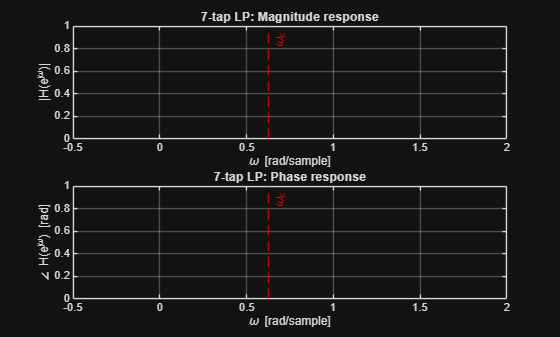

[H7, w7] = freqz(B_LP7, A_LP7, Nfft);

figure;
subplot(2,1,1);
plot(w7, abs(H7), 'LineWidth', 1.5); grid on;
hold on; xline(wc, '--r', '\omega_c');
xlabel('\omega [rad/sample]'); ylabel('|H(e^{j\omega})|');
title('7-tap LP: Magnitude response');

subplot(2,1,2);
plot(w7, unwrap(angle(H7)), 'LineWidth', 1.5); grid on;
hold on; xline(wc, '--r', '\omega_c');
xlabel('\omega [rad/sample]'); ylabel('\angle H(e^{j\omega}) [rad]');
title('7-tap LP: Phase response');

## 1-E) Impulse response (7 taps)

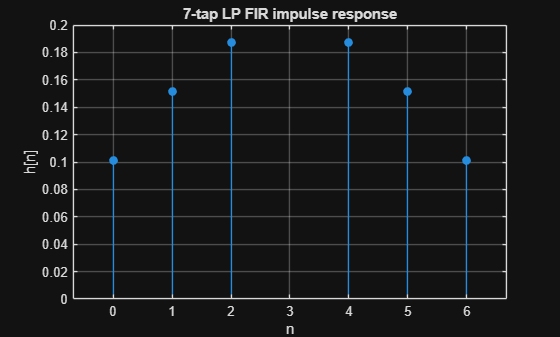

figure;
stem(0:M1, B_LP7, 'filled'); grid on;
xlabel('n'); ylabel('h[n]');
title('7-tap LP FIR impulse response');

## 1-F) 51-tap LP FIR

Ntaps51 = 51;
M51 = Ntaps51 - 1;            % 50
K51 = (Ntaps51 - 1)/2;        % 25

n_trunc51 = -K51:K51;
hLP_trunc51 = hLP_ideal(n_trunc51);
bLP51 = hLP_trunc51;

fprintf('\n--- Exercise 1-F ---\n');


--- Exercise 1-F ---


fprintf('Ntaps = %d, M = %d, K = %d\n', Ntaps51, M51, K51);

Ntaps = 51, M = 50, K = 25


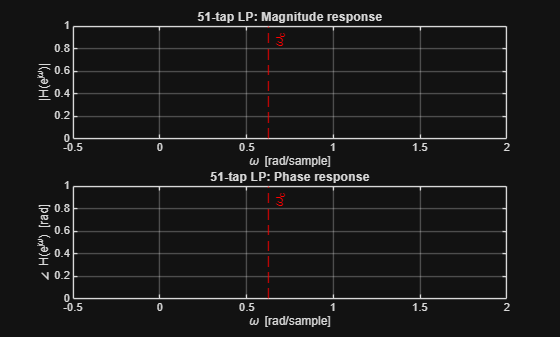


[H51, w51] = freqz(bLP51, 1, Nfft);

figure;
subplot(2,1,1);
plot(w51, abs(H51), 'LineWidth', 1.5); grid on;
hold on; xline(wc, '--r', '\omega_c');
xlabel('\omega [rad/sample]'); ylabel('|H(e^{j\omega})|');
title('51-tap LP: Magnitude response');

subplot(2,1,2);
plot(w51, unwrap(angle(H51)), 'LineWidth', 1.5); grid on;
hold on; xline(wc, '--r', '\omega_c');
xlabel('\omega [rad/sample]'); ylabel('\angle H(e^{j\omega}) [rad]');
title('51-tap LP: Phase response');

## 1-G) Comparison 7 vs 51 taps

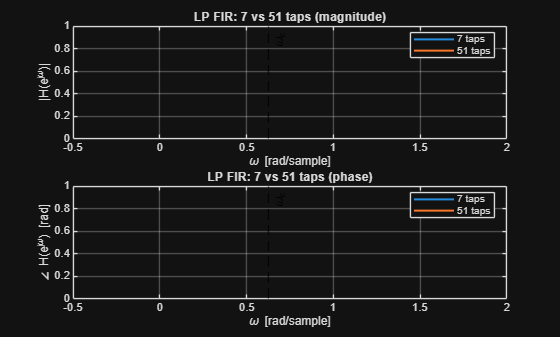

figure;
subplot(2,1,1);
plot(w7,  abs(H7),  'LineWidth', 1.5); hold on;
plot(w51, abs(H51), 'LineWidth', 1.5);
grid on; xline(wc, '--k', '\omega_c');
legend('7 taps', '51 taps', 'Location','best');
xlabel('\omega [rad/sample]'); ylabel('|H(e^{j\omega})|');
title('LP FIR: 7 vs 51 taps (magnitude)');

subplot(2,1,2);
plot(w7,  unwrap(angle(H7)),  'LineWidth', 1.5); hold on;
plot(w51, unwrap(angle(H51)), 'LineWidth', 1.5);
grid on; xline(wc, '--k', '\omega_c');
legend('7 taps', '51 taps', 'Location','best');
xlabel('\omega [rad/sample]'); ylabel('\angle H(e^{j\omega}) [rad]');
title('LP FIR: 7 vs 51 taps (phase)');

## Exercise 2 – FIR Band-pass (Fourier-transform design)

## 2-A) Angular cutoffs and ideal BP impulse response

Fs2 = 8000;
FL = 2000;
FH = 2400;

wL = 2*pi*FL/Fs2;    % 0.5*pi
wH = 2*pi*FH/Fs2;    % 0.6*pi

fprintf('\n--- Exercise 2-A ---\n');


--- Exercise 2-A ---


fprintf('omega_L = %.6f rad/sample (%.3f*pi)\n', wL, wL/pi);

omega_L = 1.570796 rad/sample (0.500*pi)


fprintf('omega_H = %.6f rad/sample (%.3f*pi)\n', wH, wH/pi);

omega_H = 1.884956 rad/sample (0.600*pi)



NtapsBP = 9;
M_BP = NtapsBP - 1;         % 8
K_BP = (NtapsBP - 1)/2;     % 4
fprintf('Ntaps = %d, M = %d, K = %d\n', NtapsBP, M_BP, K_BP);

Ntaps = 9, M = 8, K = 4



% Ideal BP impulse response (infinite)
hBP_ideal = @(n) (n==0).*((wH - wL)/pi) + ...
                 (n~=0).*((sin(wH*n) - sin(wL*n))./(pi*n));

nBP_trunc = -K_BP:K_BP;
hBP_trunc = hBP_ideal(nBP_trunc);

fprintf('hBP_trunc (n=-4..4) = [');

hBP_trunc (n=-4..4) = [

fprintf(' %.6f', hBP_trunc);

 0.075683 0.043737 -0.093549 -0.015579 NaN -0.015579 -0.093549 0.043737 0.075683

fprintf(' ]\n');

 ]


## 2-B) BP FIR coefficients (9 taps)

bBP9 = hBP_trunc;
fprintf('\n--- Exercise 2-B ---\n');


--- Exercise 2-B ---


fprintf('bBP9 = [');

bBP9 = [

fprintf(' %.6f', bBP9);

 0.075683 0.043737 -0.093549 -0.015579 NaN -0.015579 -0.093549 0.043737 0.075683

fprintf(' ]\n');

 ]


## 2-C) Magnitude and phase for 9-tap BP

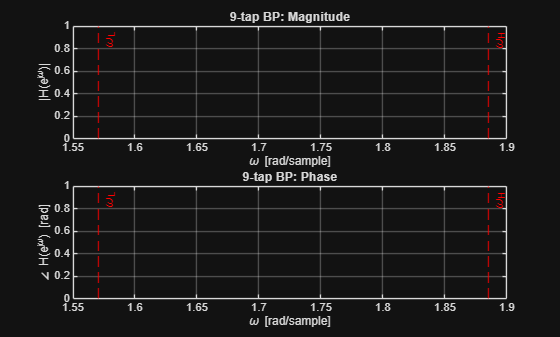

[HBP9, wBP9] = freqz(bBP9, 1, Nfft);

figure;
subplot(2,1,1);
plot(wBP9, abs(HBP9), 'LineWidth', 1.5); grid on;
hold on;
xline(wL, '--r', '\omega_L');
xline(wH, '--r', '\omega_H');
xlabel('\omega [rad/sample]'); ylabel('|H(e^{j\omega})|');
title('9-tap BP: Magnitude');

subplot(2,1,2);
plot(wBP9, unwrap(angle(HBP9)), 'LineWidth', 1.5); grid on;
hold on;
xline(wL, '--r', '\omega_L');
xline(wH, '--r', '\omega_H');
xlabel('\omega [rad/sample]'); ylabel('\angle H(e^{j\omega}) [rad]');
title('9-tap BP: Phase');

## 2-D) 101-tap BP design and comparison

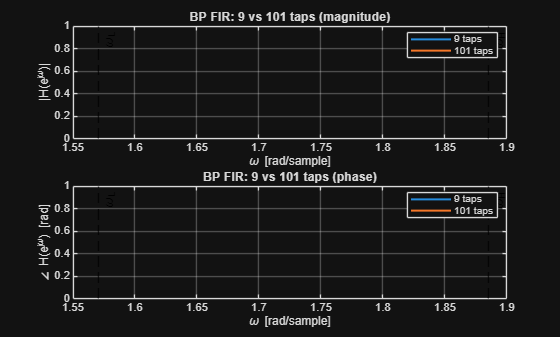

NtapsBP101 = 101;
M_BP101 = NtapsBP101 - 1;        % 100
K_BP101 = (NtapsBP101 - 1)/2;    % 50

nBP_trunc101 = -K_BP101:K_BP101;
hBP_trunc101 = hBP_ideal(nBP_trunc101);
bBP101 = hBP_trunc101;

[HBP101, wBP101] = freqz(bBP101, 1, Nfft);

figure;
subplot(2,1,1);
plot(wBP9,   abs(HBP9),   'LineWidth', 1.5); hold on;
plot(wBP101, abs(HBP101), 'LineWidth', 1.5);
grid on;
xline(wL, '--k', '\omega_L');
xline(wH, '--k', '\omega_H');
legend('9 taps', '101 taps', 'Location','best');
xlabel('\omega [rad/sample]'); ylabel('|H(e^{j\omega})|');
title('BP FIR: 9 vs 101 taps (magnitude)');

subplot(2,1,2);
plot(wBP9,   unwrap(angle(HBP9)),   'LineWidth', 1.5); hold on;
plot(wBP101, unwrap(angle(HBP101)), 'LineWidth', 1.5);
grid on;
xline(wL, '--k', '\omega_L');
xline(wH, '--k', '\omega_H');
legend('9 taps', '101 taps', 'Location','best');
xlabel('\omega [rad/sample]'); ylabel('\angle H(e^{j\omega}) [rad]');
title('BP FIR: 9 vs 101 taps (phase)');


fprintf('\nDone.\n');


Done.
